clear all;
close all;
clc;

## User Input

f_prf = 200;            % PRF frequency, Hz
Vbus = 340;             % DRSSTC bus voltage, V
I_ocd_lim = 300;        % OCD current limit, A    
N = 4;                  % number of resonant cycles to plot
phi = 0;                % Phase of inverter switching waveform w.r.t primary current, rad
Lp = 8e-6;              % Primary coil inductance, H
C_mmc = 0.045e-6;       % MMC Bank capacitance, F
R_loop = 100e-3;        % Total current loop parasitic ESR (PCB pours, connectors, wires etc.), Ohm
L_esr = 10e-3;          % Primary coil ESR (Ohms)
MMC_esr = 10e-3;        % MMC Bank total ESR (Ohms)
% Total current loop parasitic series resistance (Ohms)
Req = R_loop + L_esr + MMC_esr;         

## Derived variables

t_prf = 1/f_prf;    % PRF period, sec

% DRSSTC resonant frequency, Hz
f0 = 1/(2*pi*sqrt(Lp*C_mmc));
t0 = 1/f0;              % DRSSTC resonant period, sec
w0 = 2*pi*f0;           % angular resonant freq, rad/s
% sampling freq, Hz (over-sample to see higher-order harmonics)
fs = f0*10000;
% sim time step, sec
ts = 1/fs;              
t=0:ts:N*t0;            % time-series
t_usec = t*1e6;

## Primary Current Ring-Down

I_sd = I_ocd_lim; % Primary current at inverter shutdown (when driven portion of PRF ends), A

alpha = Req/(2*Lp);
omega_d = sqrt((w0^2)-(alpha^2));

% Generate ring-down over one PRF cyle
t_rd=0:ts:t_prf;
i_rd = I_sd*exp(-alpha*t_rd).*cos(omega_d*t_rd);

fprintf("Natural resonant frequency: %0.4f kHz",f0/1e3);

Natural resonant frequency: 265.2582 kHz

fprintf("Damped resonant frequency: %0.4f kHz",omega_d/(2*pi*1e3));

Damped resonant frequency: 265.2556 kHz

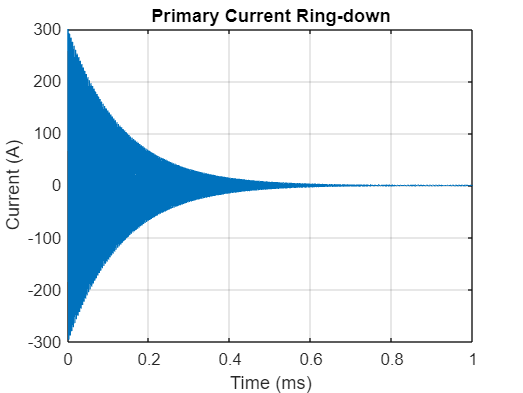


figure()
idx = (t_rd <= 1e-3); 
plot(t_rd(idx)*1e3,i_rd(idx));
xlabel('Time (ms)');
ylabel('Current (A)')
grid on;
title("Primary Current Ring-down")

## Primary Current Ring-up

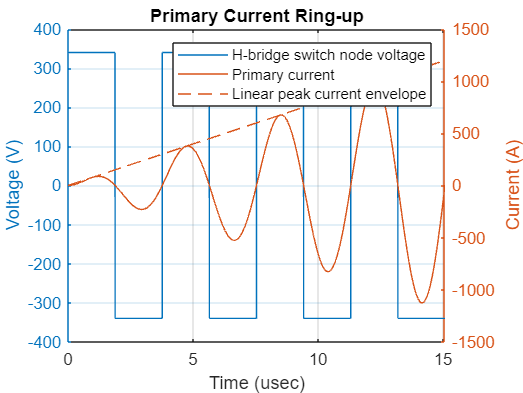

A = t/t0 * I_ocd_lim;           % Linearly rising peak current envelope
i_pri = A.*sin(w0*t);           % Primary current

v_inv = Vbus*sign(sin(w0*t+phi));   % Inverter switch node voltage

figure();
yyaxis left
plot(t_usec,v_inv);
xlabel("Time (usec)");
ylabel("Voltage (V)");
grid on;

yyaxis right
plot(t_usec, i_pri);
hold on;
plot(t_usec,A,'--');     % plot peak current envelope
hold on;
ylabel('Current (A)');
legend("H-bridge switch node voltage", "Primary current", "Linear peak current envelope");
%legend("$\text{H-bridge switch node voltage}$","$Primary current$","$Linear peak current envelope$",'Interpreter', 'latex','FontSize', 12);
title('Primary Current Ring-up')

## Square Wave Demo

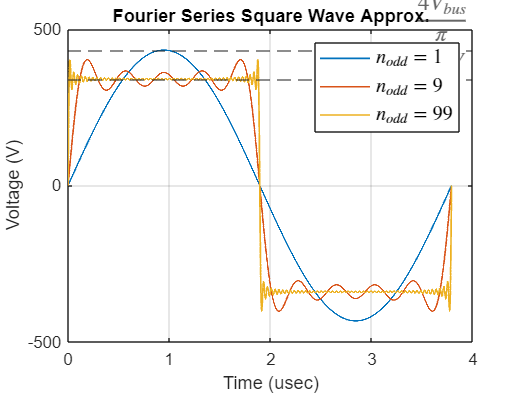

square_wave_approx_demo

## Primary Current and Primary Coil and MMC Voltage

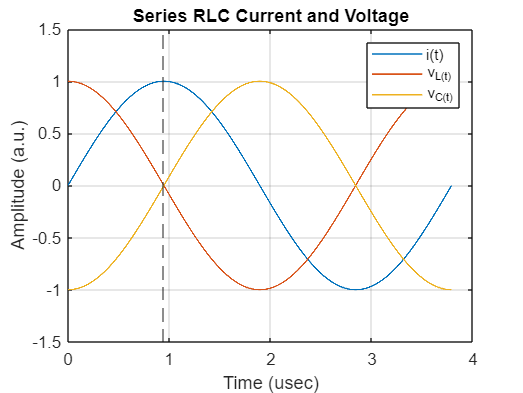

phi_l = pi/2;          % Primary coil voltage leads primary current by 90 deg
phi_mmc = -pi/2;    % MMC voltage lags primary current by 90 deg
i = sin(w0*t);
v_l = sin(w0*t+phi_l); 
v_c = sin(w0*t+phi_mmc); 

t_usec = t*1e6;
lineWidth = 1;
figure();
plot(t_usec,i,"LineWidth",lineWidth);
hold on;
plot(t_usec,v_l,"LineWidth",lineWidth);
hold on;
plot(t_usec,v_c,"LineWidth",lineWidth);
xline(((pi/2)/w0)*1e6,'--');    % Plot vertical line at peak current
grid on;
legend("i(t)","v_L(t)","v_C(t)");
ylabel('Amplitude (a.u.)')
xlabel('Time (usec)');
ylim([-1.5 1.5]);
title('Series RLC Current and Voltage')

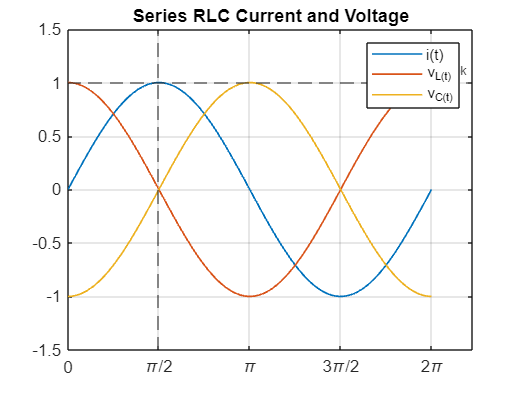



% 1. Define your x-axis data in radians
x = linspace(0, 2*pi, 100);
i = sin(x);
v_l = sin(x+phi_l); 
v_c = sin(x+phi_mmc); 

figure()
plot(x, i, 'LineWidth', lineWidth);
hold on;
plot(x, v_l, 'LineWidth', lineWidth);
hold on;
plot(x, v_c, 'LineWidth', lineWidth);
grid on;
xline(pi/2,'--');    % Plot vertical line at peak current
yline(1,'--', "i_{pk}");    % Plot vertical line at peak current
legend("i(t)","v_L(t)","v_C(t)");
title('Series RLC Current and Voltage');
ylim([-1.5 1.5]);
ax = gca;   %Get the current axes handle
ax.XTick = 0 : pi/2 : 2*pi; % Set the locations for the tick marks (intervals of pi/2)
ax.XTickLabel = {'0', '\pi/2', '\pi', '3\pi/2', '2\pi'}; % Assign the corresponding pi-fraction labels

## Power Reduction Rule Plot


y = (1 + cos(2*x))/2;
y_mean = mean(y)

y_mean = 0.5050

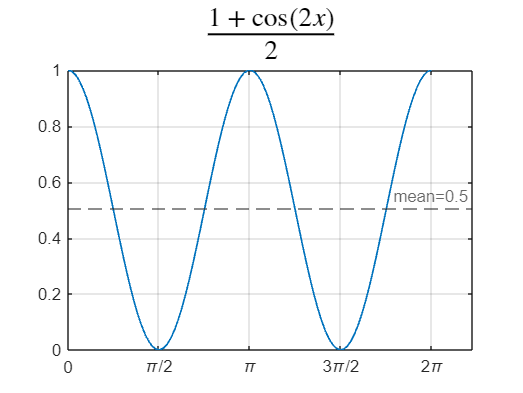


lineWidth = 1;

figure()
plot(x, y, 'LineWidth', lineWidth);
grid on;
yline(y_mean,'--', "mean=0.5");   
%legend("i(t)");
title('$\frac{1+\cos(2x)}{2}$', 'Interpreter', 'latex', 'FontSize', 16);
ax = gca;   %Get the current axes handle
ax.XTick = 0 : pi/2 : 2*pi; % Set the locations for the tick marks (intervals of pi/2)
ax.XTickLabel = {'0', '\pi/2', '\pi', '3\pi/2', '2\pi'}; % Assign the corresponding pi-fraction labels

## Ring-down Termination

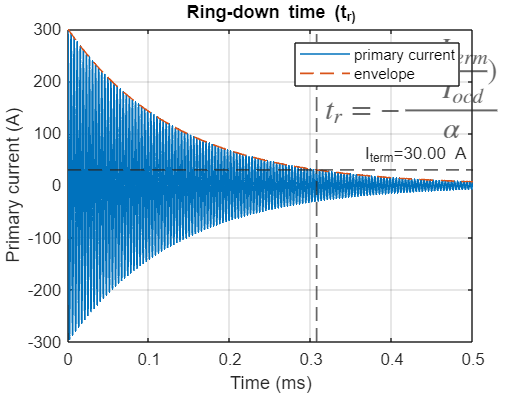

fs = f0*100;
ts = 1/fs;  % sim time step, sec
fb = 200;
tb = 1/fb;  % PRF period
t=0:ts:1e-3;           
t_msec = t*1e3;

alpha = Req/(2*Lp);          % damping coefficient
wd = sqrt(w0^2-alpha^2);     % damped resonant frequency

% Primary current envelope
a_t = I_ocd_lim.*exp(-alpha*t);
% Primary current
i_pri = a_t.*cos(wd*t);

epsilon = 0.1;
I_term = epsilon * I_ocd_lim;
tr = -log(I_term/I_ocd_lim)/alpha;
tr_ms = tr*1e3;

figure()
plot(t_msec,i_pri,'LineWidth', lineWidth);
hold on;
plot(t_msec, a_t, '--','LineWidth', lineWidth);
yline(I_term, '--', sprintf("I_{term}=%0.2f A",I_term),'LineWidth', lineWidth);
tr_label = '$t_r=- \frac{ln(\frac{I_{term}}{I_{ocd}})}{\alpha}$';
xline(tr_ms, '--', tr_label,'LineWidth', lineWidth, 'LabelOrientation', "horizontal", 'Interpreter', 'latex', "FontSize",18, "FontWeight","bold");
%xline(tr_ms, '--', sprintf("t_r=%0.2f",tr_ms),'LineWidth', lineWidth, 'LabelOrientation', "horizontal");
xlabel('Time (ms)');
ylabel("Primary current (A)")
xlim([0 0.5]);
grid on;
legend("primary current", "envelope");
title('Ring-down time (t_r)');